# MIMO Simulation at 28 GHz in an Indoor Environment

### Ozlem Yildiz    zy2043    

### Ufuk Usubutun    uu2001

In this project, we are aiming to visualize the performance of a MIMO OFDM system on an indoor enviroment. Thanks to our classmate Mingsheng, we have raytracing data of an indoor space for a fixed Tx location and a whole range of different Rx points.

We will be picking two points, one in the LOS and the other in the NLOS regime and will try to compare their characteristics.

#### Loading Data

load roomPathData.mat

rxPos = pathData.rxPos;
nrxPos = size(rxPos, 1);

txPos = pathData.txPos;

npaths = pathData.npaths;
linkState = pathData.linkState;

The code below is copied from indoorDataDemo.mlx in order to visualize the data using the DataMapper class. We would like to choose points to evaluate the performance of MIMO in one LOS and one NLOS scenario:

mapper = DataMapper(pathData.rxPos, pathData.posStep);

clf;
noDataValue = 3;  % Use this value for positions with no data

% Legend labels
legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

% Call the plot.  Use `plotHold=true` to hold the plot so we can overlay
% other items
mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);

% Overlay the TX position
plot(txPos(1), txPos(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'TX');
%hold off;

% Display the legend
legend('Location', 'SouthEast');

By examination we chose the locations in the following indices for evaluation.

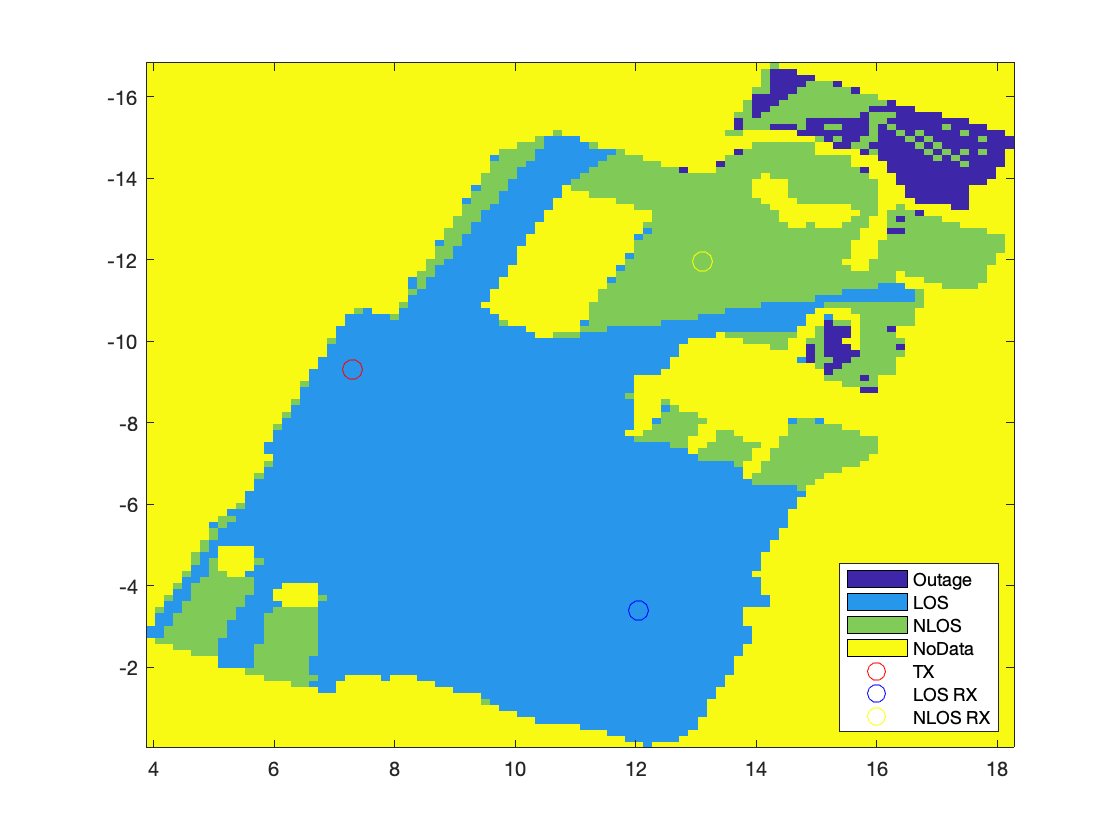

los_ind = 930;
nlos_ind = 4013;
plot(rxPos(los_ind,1), rxPos(los_ind,2), 'bo', 'MarkerSize', 10, 'DisplayName', 'LOS RX');
plot(rxPos(nlos_ind,1), rxPos(nlos_ind,2), 'yo', 'MarkerSize', 10, 'DisplayName', 'NLOS RX');
hold off;

Let's now build our Transmitter and Receiver Arrays for the Analysis

## Antenna Array

Demo 'mimoCapacity' has been taken into consideration. High-dimensional antenna arrays are used because of the carrier frequency. 

- TX: 4x4 URA 

- RX:  8x1 ULA

 The paths are angularly clustered so the channel has lower rank. 

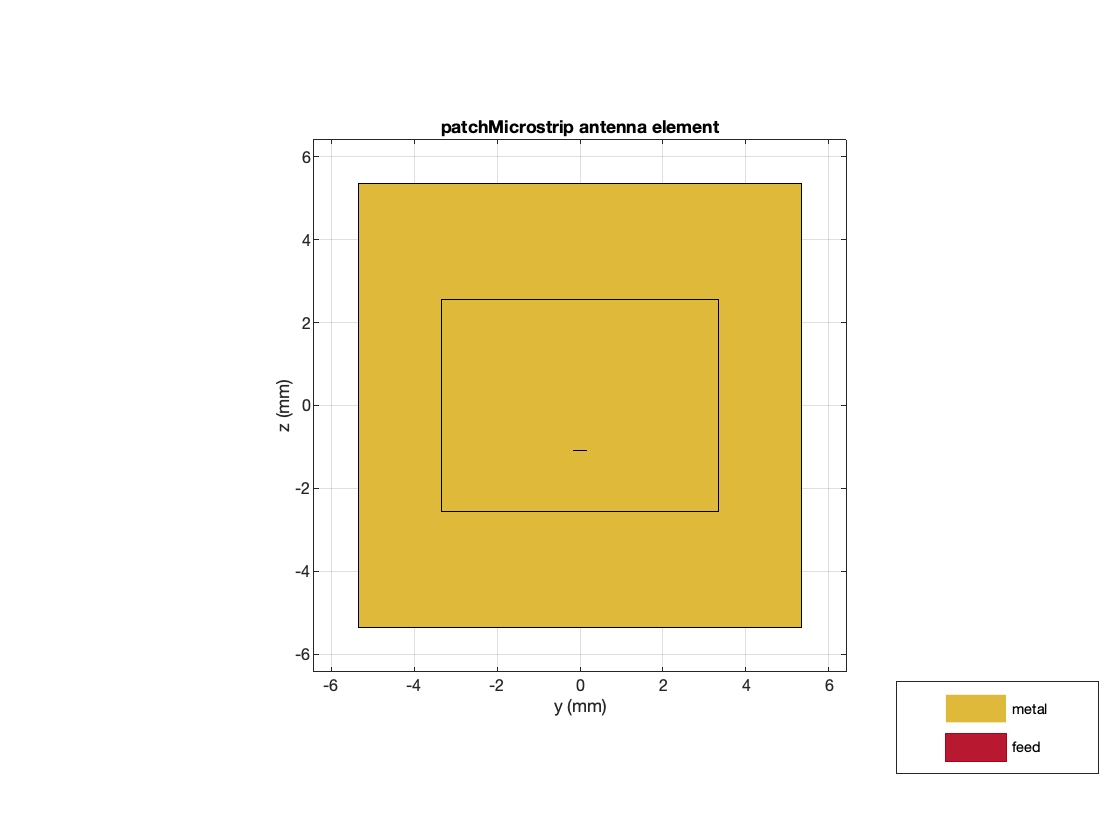

    %elem = design(fractalCarpet, fc);
    elem = design(patchMicrostrip, fc);
    elem.Tilt = 90;
    elem.TiltAxis = [0 1 0];
    elem.show();
    view(90,0)

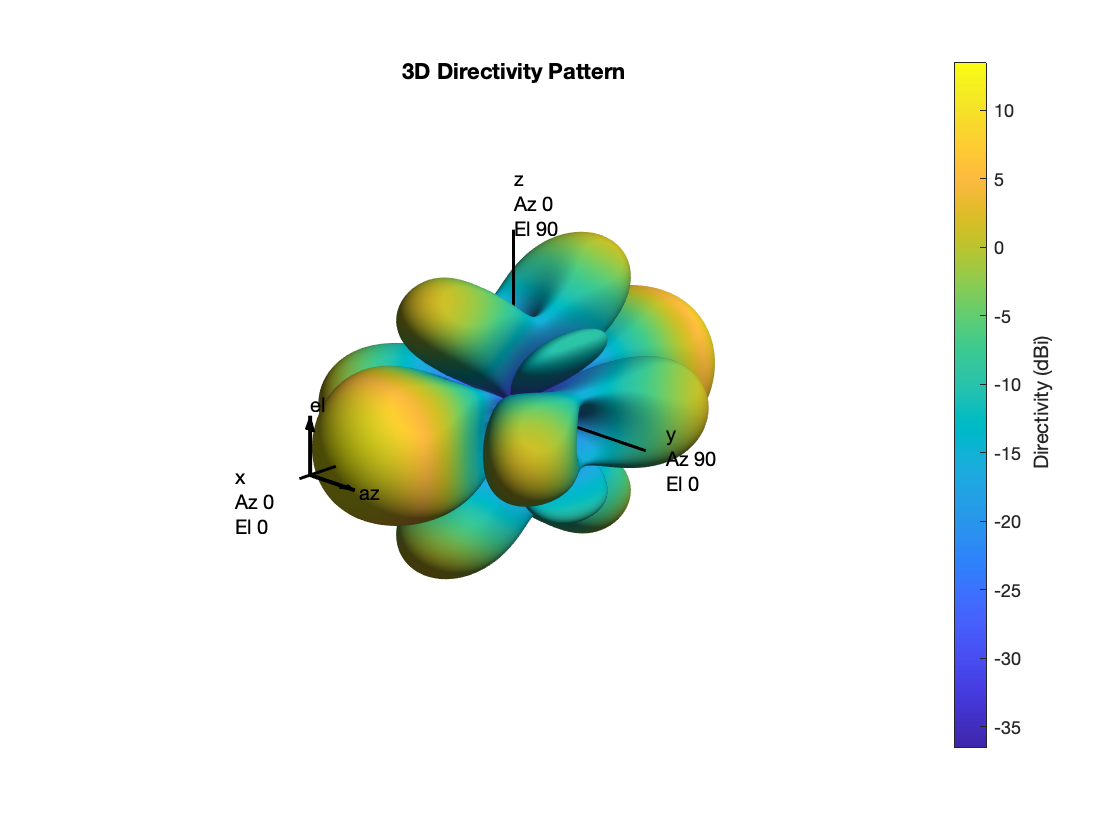

    lambda = physconst('LightSpeed')/fc;
    
    % Array parameters
    dsep = 0.5*lambda;   % element spacing
    nantRx = 8;          % Number of RX elements
    nantTx = [4,4];      % Number of TX elements
    
    
    arrRx = phased.ULA(nantRx,dsep,'ArrayAxis', 'x');
    arrTx = phased.URA(nantTx,dsep,'ArrayNormal','x');
    
    arrTx.pattern(fc)

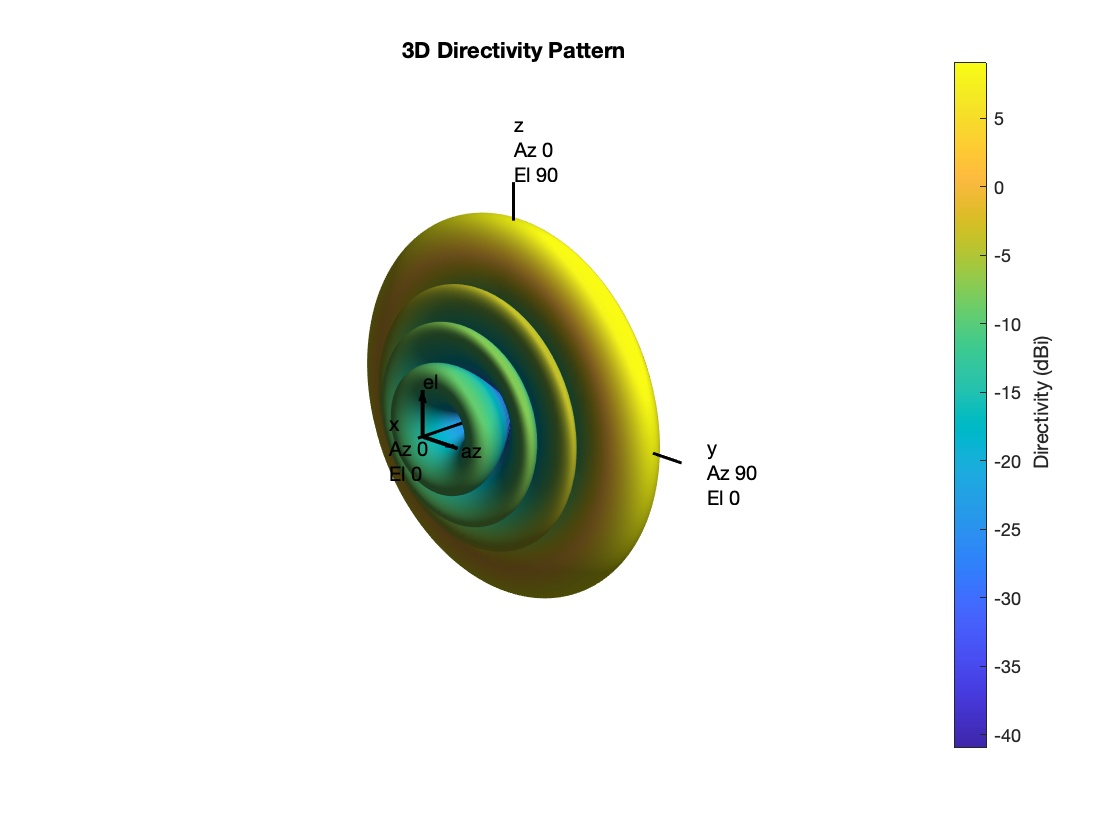

    arrRx.pattern(fc)

## Tx and Rx Arrays 

Creation of Tx and Rx Arrays using the patch antenna element of our choice:

    arrPlatformTx = ArrayPlatform('elem', elem, 'arr', arrTx, 'fc', fc);
    arrPlatformTx.computeNormMatrix();
    
    arrPlatformRx =  ArrayPlatform('elem', elem, 'arr', arrRx, 'fc', fc);
    arrPlatformRx.computeNormMatrix();

## Simulations!

We can now start our analysis!

points = [los_ind, nlos_ind];
case_name = ["LOS", "NLOS"];

for loop_ind = 1:length(points)

    rx_ind = points(loop_ind)

rx_ind = 930

rx_ind = 4013

    fc = pathData.fc;
    
    %Angels
    
    aoaAz = pathData.aoaAz(rx_ind, :)';
    aoaEl = pathData.aoaEl(rx_ind, :)';
    aodAz = pathData.aodAz(rx_ind, :)';
    aodEl = pathData.aodEl(rx_ind, :)';
    
    pl = pathData.pl(rx_ind, :);
    dly = pathData.dly(rx_ind,:)';
    %gain = pathData.gain(rx_ind,:)';
    
    posStep = pathData.posStep;

## Situtation of Arriving Paths at The Receiver

Let's look at the Azimuth Arrival Angles of various different paths at the receiver for the two locations we chose. As a rule of thumb, more diversity in paths means more capacity!

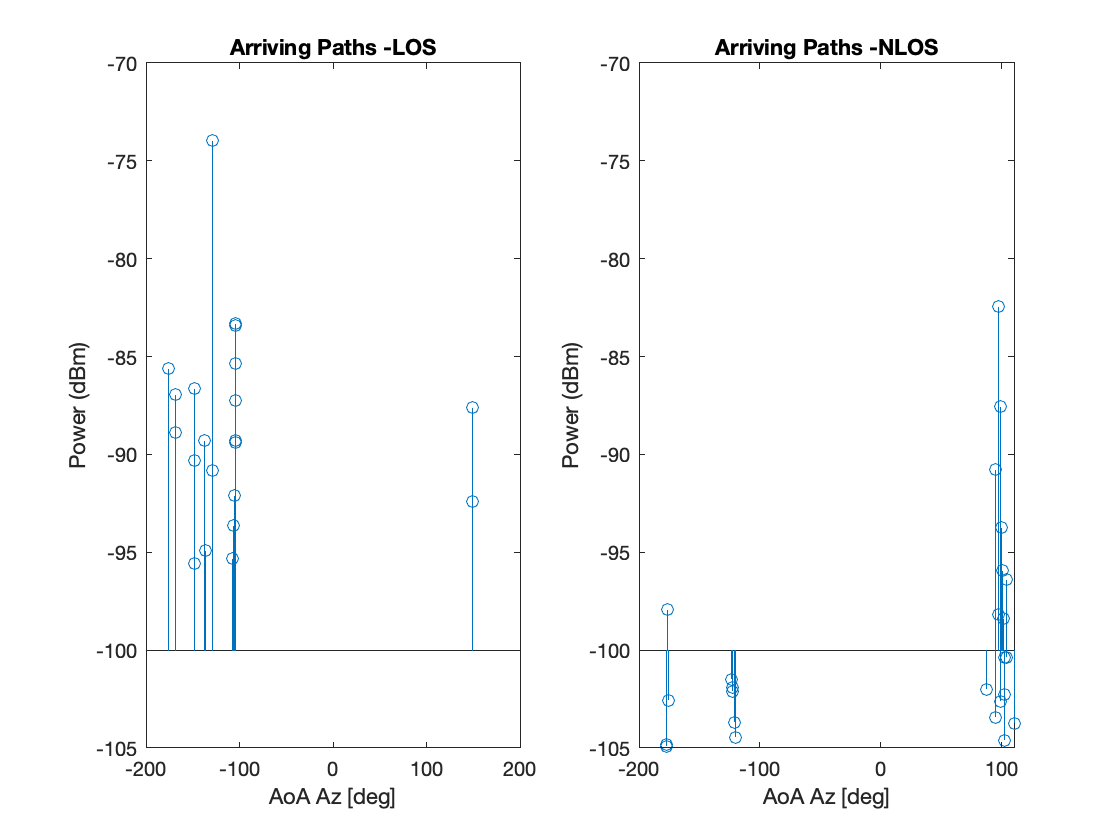

    txPow = 5; %dBm
    Ekt = -174;  % Thermal noise
    
    gain = txPow - pl';
    
    figure(1);
    subplot(1,2,loop_ind)

    stem(aoaAz, gain,'BaseValue',-100);
    title(strcat('Arriving Paths - ',case_name(loop_ind)))
    ylabel('Power (dBm)');
    xlabel('AoA Az [deg]');
    ylim([-105 -70])
    

This graph shows that for the cases of LOS and NLOS we choose, the LOS case seems to have more diversity in terms of arrival directions. Whereas on the NLOS case, all arrivals seem to be clustered in a single direction. We might expect to see a similar pattern in the SVD analysis of the Channel where we will look at virtual paths.

## Frequency Domain Channel

Using the 5G NR toolbox and classes for the Beamforming lab we create the channel grid.

    SubcarrierSpacing = 120;    % SCS in kHZ
    NRB = 61;  % number of resource blocks
    nscPerRB = 12;  % number of sub-carriers per RB
    
    BW = SubcarrierSpacing*1e3*NRB*nscPerRB;
    
    carrierConfig = nrCarrierConfig(...
        'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
    waveformConfig = nrOFDMInfo(carrierConfig);

Channel for one slot (using the MIMO channel class file used for labs):

    Enoise = Ekt + 10*log10(BW);%  % noise energy dB
    fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformTx, 'rxArrPlatform', arrPlatformRx, ...
        'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
        'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);
    frameNum = 0;
    slotNum = 0;
    [chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

Let's now look at the eigenvalue decomposition of the channel averaged over time and frequency to look at availability of virtual paths, i.e. diversity (H'*H = VDV')

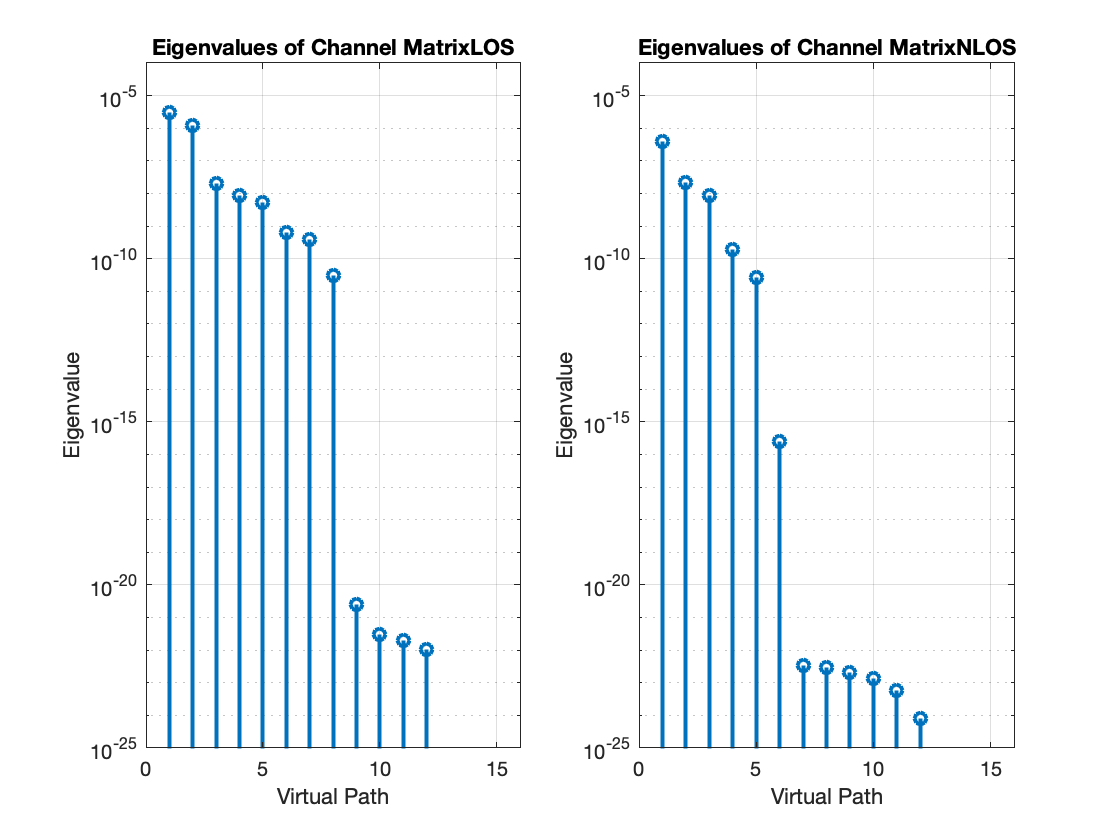

    temp = pagemtimes(pagectranspose(chanGrid),chanGrid);
    temp = mean(temp, [3 4]);
    [V,D] = eig(temp);
    
    
    figure(2)
    subplot(1,2,loop_ind)
    stem(1:length(diag(D)), flip(diag(D)), 'LineWidth', 2)
    set(gca,'yscal','log')
    grid on
    xlabel('Virtual Path')

    ylabel('Eigenvalue')
    ylim([1e-25 1e-4])
    title(strcat('Eigenvalues of Channel Matrix',case_name(loop_ind)))
    

Just as we expected to see looking at the arrival patterns of signals, For the LOS case it seems like we have 2 virtual paths that are the most powerful. For the NLOS case we seem to have only 1.

    % Capacity
    C = log2(real(det( eye(size(temp)) + db2pow(txPow)*temp/noiseVar ))  )

C = 52.9555

C = 27.5412

The capacity seems to be almost half in the NLOS case we happened obtain less powerful paths. 

## Precoding for this Channel

We will now choose the number of virtual paths to use for this channel. Looking at the eigenvalue plot suggests us that we would be able to best take advantage of 2 paths in the chosen LOS case and only 1 path in the NLOS case. However, to keep the Matlab Live Script file simple and to better see what happens if we allocate power to weak paths, let's choose the number of virtual paths to be equal to 3. 

    numVirtual = 3;  

And let's obtaine a precode matrix by choosing the 3 strongest virtual paths.

    Precoder = V(:,end-numVirtual+1:end);

Let's have the same approach we had at the final exam and define a new channel A to include precoding and the actual channel (A = H*Precoder)

    A = pagemtimes(chanGrid,Precoder);

Now for the transmitter we create a pdfschConfig as usual, but we now have NumLayers = nstream. So we create a tx object.

    mcsInd = 12;
    
    Modulation = '16QAM';
    targetCodeRate = 434/1024;
    
    pdschConfig = nrPDSCHConfig(...
        'Modulation', Modulation, ...
        'PRBSet', (0:NRB-1), ...
        'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
        'PTRS', nrPDSCHPTRSConfig(),...
        'NumLayers', 1);
    tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
    % the transmitter class is modified to have multiple layers and scale
    % the power per layer to keep the total power equal no matter the
    % choice of layers

Now we create a txGrid

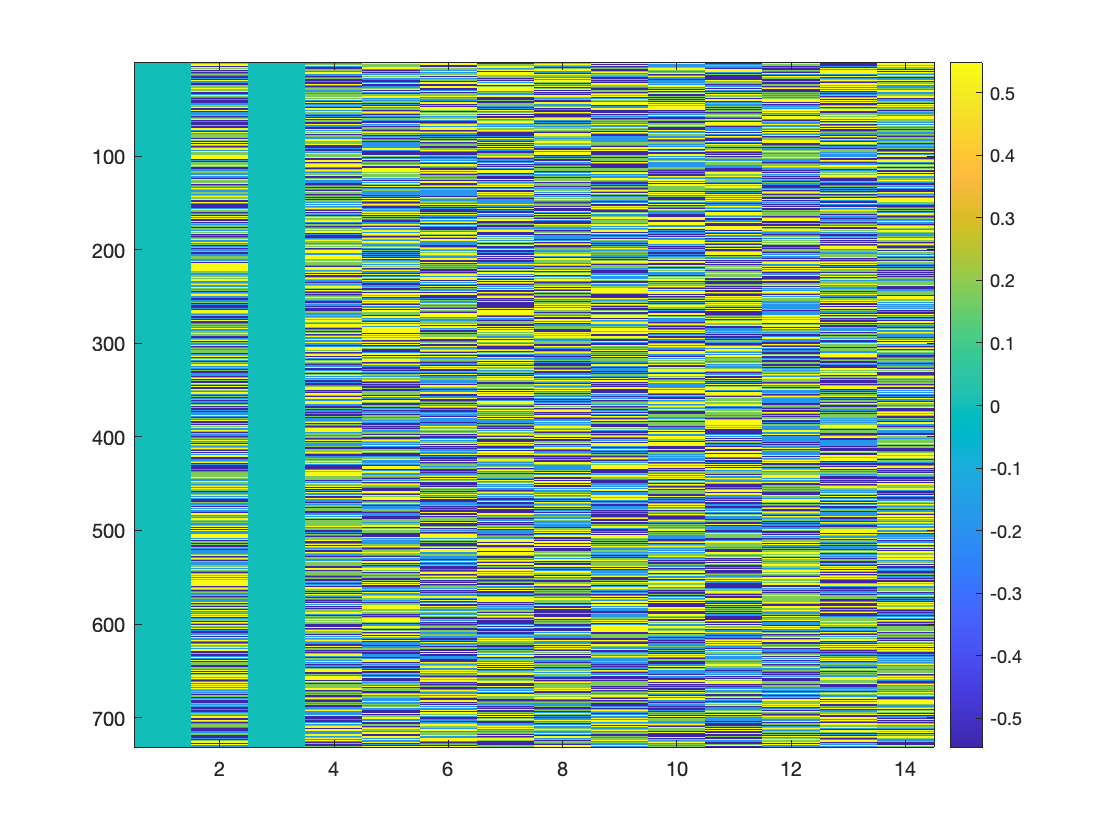

    txGrid = tx.step(numVirtual);
    figure(3)
    imagesc(real(squeeze(txGrid(1,1,:,:))))

    colorbar

We precode the txGrid by the precoder calculated above

    txGridPrecoded = pagemtimes(Precoder,txGrid);

## Channel + Noise

    rxGrid = pagemtimes(chanGrid,txGridPrecoded);
    rxGrid = rxGrid + sqrt(noiseVar/2).*( randn(size(rxGrid)) + 1i.*randn(size(rxGrid)));

## Receiver

Removel of Precoding with LMMSE

    alpha = db2pow(txPow)/(noiseVar*prod(nantTx));
    
    % implemented by following LMMSE decoder from slide 45 of MIMO Unit
    temp = pagemtimes(pagectranspose(A),A);
    temp = alpha*temp +  repmat( eye(size(temp,[1,2])), [1, 1, size(temp, [3 4]) ]) ;
    
    F = zeros(size(temp));
    for i=1:size(temp,3)
        for j=1:size(temp,4)
            F(:,:,i,j) = temp(:,:,i,j)^(-1);
        end
    end
    F = alpha*pagemtimes(F, pagectranspose(A));
    
    rxGridEq = squeeze(pagemtimes(F,rxGrid)); %Equalizing received signal
    chanGridEq = pagemtimes(F,A); %Equalized channel


SNR of Virtual Channels

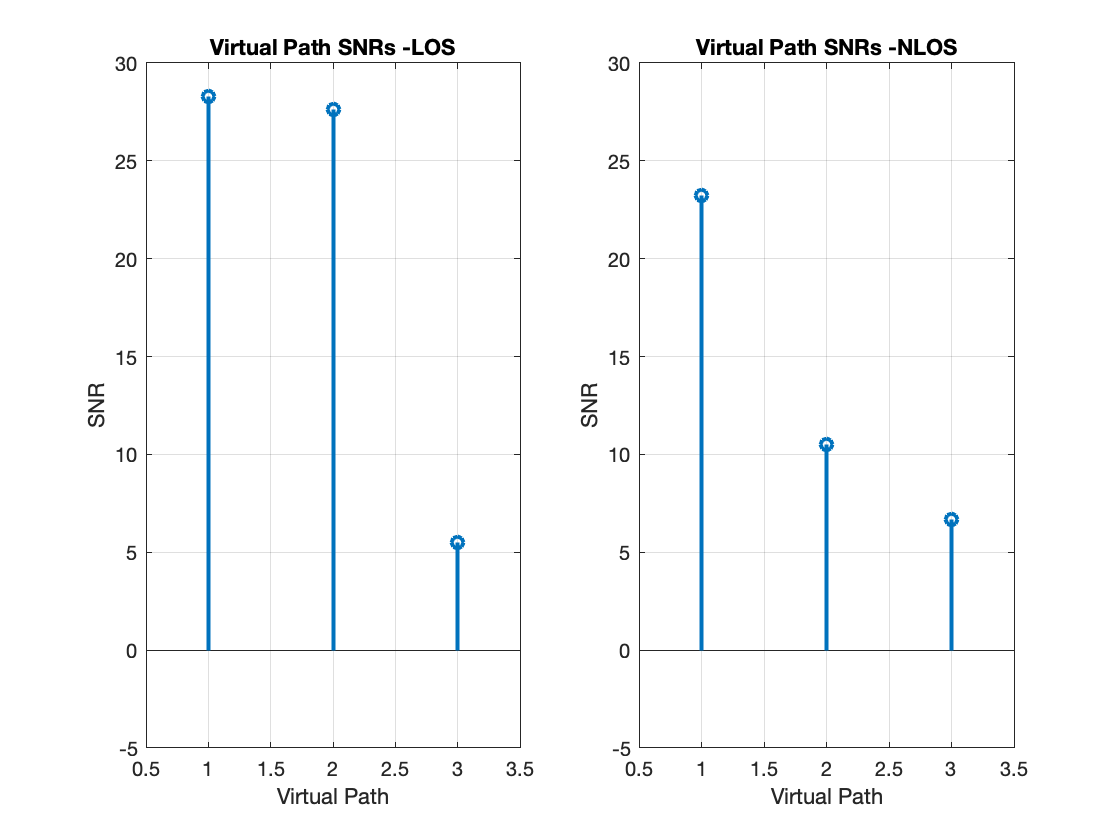

    % we can use the same temp as above which conatins (A'*A)
    % temp = pagemtimes(pagectranspose(G),G);
    % temp = alpha*temp +  repmat( eye(size(temp,[1,2])), [1, 1, size(temp, [3 4]) ]) ;
    
    % implemented by following SINR per channel from slide 48 of MIMO Unit
    
    QLMMSE = zeros(size(temp));
    for i=1:size(temp,3)
        for j=1:size(temp,4)
            QLMMSE(:,:,i,j) = temp(:,:,i,j)^(-1);
        end
    end
    
    snrLin = real(1./diag(mean(QLMMSE,[3 4])) - 1);
    snrdB = pow2db(snrLin);
    figure(4)
    subplot(1,2,loop_ind)

    stem((1:numVirtual) ,flip(snrdB), 'LineWidth', 2)
    grid on
    xlabel('Virtual Path')
    ylabel('SNR')
    title(strcat('Virtual Path SNRs - ',case_name(loop_ind)))
    xlim([0.5 numVirtual+0.5])
    ylim([-5 30])
    noiseVarStreams = sqrt(1./snrLin);

Demodulation of bits

    rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
    rx.step(rxGridEq, chanGridEq, noiseVarStreams,numVirtual);
    % the receiver in the same way is modified to multiply the input power
    % by number of virtual paths to accomodate our modification with the 5G
    % NR functions
    % At this step this process diverges from 5G NR protocols as the grid is
    % already equalized together while the precoding was removed.

## Results

    rxBits = rx.rxBits;
    numBitsinVir = size(tx.txBits{1},1);
    txBits = zeros( numVirtual*numBitsinVir, 1 );
    
    for i=1:numVirtual
        txBits( (i-1)*numBitsinVir+1 : (i)*numBitsinVir) = tx.txBits{i};
    end
    
    Recvd_Correct = sum( rxBits == txBits );
    Total = length(txBits);
    
    
    %
    fprintf(case_name(loop_ind))

LOS

NLOS

    fprintf('Sent %d bits, Decoded %d correctly. BER: %f',Total,Recvd_Correct, 1-Recvd_Correct/Total)

Sent 44568 bits, Decoded 43396 correctly. BER: 0.026297

Sent 44568 bits, Decoded 43943 correctly. BER: 0.014024

end

The chosen LOS case seems to achieve a much better Bit Error Rate with the chosen parameters (as expected).

Using this same code, we were able to play around with the code rate, the modulation rate and number of virtual paths to allocate power on.

Keeping the number of virtual paths close the the reality of the channel achieves the best results. While there exists a tradeoff between the chosen modulation rate and Error Rates